# ACTIVE Radar Data - Processing Data to Output SNR

### This script will, for ACTIVE input data:

- Uses func slice_SNR to calculate the peak power, the noise (how?), the SNR, and the index of the peak power.  

- Generate a Range-Doppler for the defined slice within the input data.

- Plot a large white diamond marker where the peak power is represented in the Range-Doppler.

- Saves the figure as a .PNG

#### Preperation of data

Clear current workspace

clear

Load workspace

load('my_workspace_baseline_23Jan.mat') % define workspace
inputstructure = active; % define your data input structure
inputstructure.name = "Active"; % define your data input name
inputdata = inputstructure.range_doppler_slices;
% User defined ROI indices
roi_indices_rows = 320:420;
roi_indices_cols = 65:99;
signal=zeros(1,length(inputdata));
noise=zeros(1,length(inputdata));
SNR=zeros(1,length(inputdata));
slices_range_doppler = createArrays(length(inputdata), size(inputdata{1,1}));
for i=1:length(inputdata)
    [signal(i),noise(i),SNR(i),slices_range_doppler{i},signal_idx(i)]=slice_SNR(inputdata{1,i}, roi_indices_rows, roi_indices_cols);
end   

### User to Define which range doppler slice to visualise:

k = 73; % define which slice number you want to visualise

#### Preparation of Data Storage Directory

This defines where all data generated from this script will be stored. Sub-folders are also created.

if pc ==1
    experiment_directory = local_save_directory + experiment_number;
    mkdir(experiment_directory); % create directory
    video_directory = experiment_directory + bracket + "videos";
    mkdir(video_directory); % create directory
    figure_directory = experiment_directory + bracket + "figures";
    mkdir(figure_directory); % create directory
elseif pc ==2
    display('pc 2 data storage directories to be defined by User')
elseif pc ==3
    display('pc 3 data storage directories to be defined by User')
else
    display('Undefined by User')
end    

Define Range-Doppler user input configuration

x = inputstructure.range_axis; % x_axis
y = inputstructure.doppler_axis; % .doppler_axis is doppler frequency [Hz] % doppler_velocity_axis; % y_axis
dynamic_range = +inf % +50; % user defined dynamic range to maximise visualisation

dynamic_range = Inf

max_range = 500 % user defined max range to maximise visualisation

max_range = 500

max_doppler = 510 % user defined max doppler to maximise visualisation

max_doppler = 510

Generate Range-Doppler image with scaled colours

figure_title = (inputstructure.name + ' Range Doppler Slice ' ...
    + k + ' of ' + length(inputdata));
fig = figure;
imagesc(x,y,slices_range_doppler{1, k},[-dynamic_range 0])
title(figure_title);
ylabel('Doppler Frequency [Hz]');
xlabel('Range (m)') ;

User to define limits of the colorbar

clim([-50 0]) % -dynamic_range
c = colorbar;
c.Label.String='Norm Power [dB]';
ylim([-max_doppler max_doppler]); % Doppler Limit
xlim([-inf max_range]);   % Range Limit
colormap jet;
hold on

Return row and column index positions for peak signal index

[idx_doppler, idx_range] = ind2sub(size(slices_range_doppler{1,k}),signal_idx(k))

idx_doppler = 204

idx_range = 12

Convert index row and column into doppler and range using active. axis

idx_range_axis = inputstructure.range_axis(idx_range)

idx_range_axis = 54.9620

idx_doppler_axis = inputstructure.doppler_axis(idx_doppler)

idx_doppler_axis = -94

Plot peak signal on top of Range-Doppler as large white diamond

plot(idx_range_axis, idx_doppler_axis...
    , "diamondk", "MarkerFaceColor","w",...
    'MarkerSize', 10)
hold off

Save generated image as .PNG

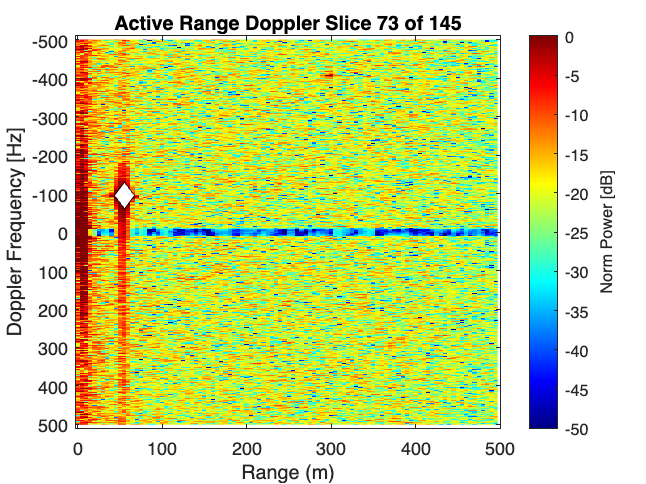

% exp_dir = figure_directory + experiment_number + '_active' + '\slice_images'; % user defined export directory
fig_name = figure_directory + bracket + figure_title;
savefig(figure_title)
saveas(fig, fig_name, 'png')

## Quantify Signal and Noise

signal; % output from slice_SNR function
noise; % output from slice_SNR function

## Define SNR in dB for all slices

User defined level of noise desired

user_defined_noise = 2  % User defiend noise

user_defined_noise = 2

Take the input data complex array and apply the awgn function

inputdata_plus_noise = createArrays(length(inputdata),...
    size(inputdata{1,1}));
for i=1:length(inputdata)
    inputdata_plus_noise{1,i} = awgn(inputdata{1,i}, user_defined_noise,...
        'measured'); % complex + awgn
end

Convert the noise induced complex array to power using the slice_SNR func

signal_plus_noise=zeros(1,length(inputdata));
noise_plus_noise=zeros(1,length(inputdata));
SNR_plus_noise=zeros(1,length(inputdata));
slices_range_doppler_plus_noise = createArrays(length(inputdata), size(inputdata{1,1}));
for i=1:length(inputdata)
    [signal_plus_noise(i),noise_plus_noise(i),SNR_plus_noise(i),...
        slices_range_doppler_plus_noise{i},...
        signal_idx_plus_noise(i)]=slice_SNR(inputdata_plus_noise{1,i}, roi_indices_rows, roi_indices_cols);
end  

Visualise the slice chosen by the user both with & without awgn applied at complex stage

figure_title = (inputstructure.name +...
    ' Range Doppler Slice '...
    + k + ' of ' + length(inputdata));
fig = figure;

subplot(2, 1, 1);
imagesc(x,y,slices_range_doppler{1, k},[-dynamic_range 0])
title(figure_title);
ylabel('Doppler Velocity [m/s]');
xlabel('Range (m)');
% User to define limits of the colorbar
clim([-50 0]) % -dynamic_range
c = colorbar;
c.Label.String='Norm Power [dB]';
ylim([-max_doppler max_doppler]); % Doppler Limit
xlim([-inf max_range]);   % Range Limit
colormap jet;

subplot(2, 1, 2);
imagesc(x,y,slices_range_doppler_plus_noise{1, k},[-dynamic_range 0])
title(figure_title + ' +' + user_defined_noise + 'dB Noise at Complex Stage');
ylabel('Doppler Velocity [m/s]');
xlabel('Range (m)');
% User to define limits of the colorbar
clim([-50 0]) % -dynamic_range
c = colorbar;
c.Label.String='Norm Power [dB]';
ylim([-max_doppler max_doppler]); % Doppler Limit
xlim([-inf max_range]);   % Range Limit
colormap jet;

Save figures to data directory

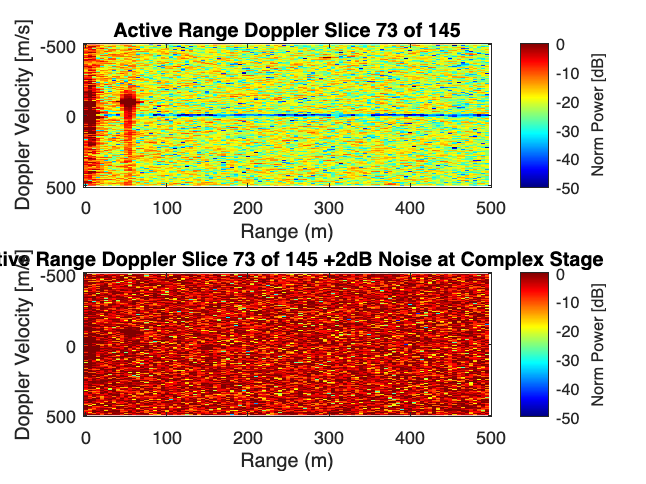

% exp_noise = repo_directory + '\bladeRAD-Rikki\figures\experiment_' + experiment_number + '_active' + '\noisy_image_comparison'; % user defined export directory
fig_name = figure_directory + bracket + figure_title;
% savefig(inputstructure.name + ' Range Doppler Slice ' + k + length(inputdata))
savefig(figure_title)
saveas(fig, fig_name + " baseline to noise comparison", 'png')

## Plot SNR against Time (?) for all slices of Active data

SNR_delta = SNR - SNR_plus_noise;
figure_title = (inputstructure.name + ' SNR for '...
    + length(inputdata) + ' Slices');
fig = figure;
plot(1:length(SNR), SNR, ...
    1:length(SNR_plus_noise), SNR_plus_noise, ...
    1:length(SNR_delta), SNR_delta)
title(figure_title);
ylabel('SNR [dB]');
xlabel('Slice No') ;
legend("SNR", 'SNR + Noise', 'SNR Delta')
grid on
%ylim([-max_doppler max_doppler]); % Doppler Limit
xlim([-inf length(SNR)]);   % Range Limit


Save figure to repo

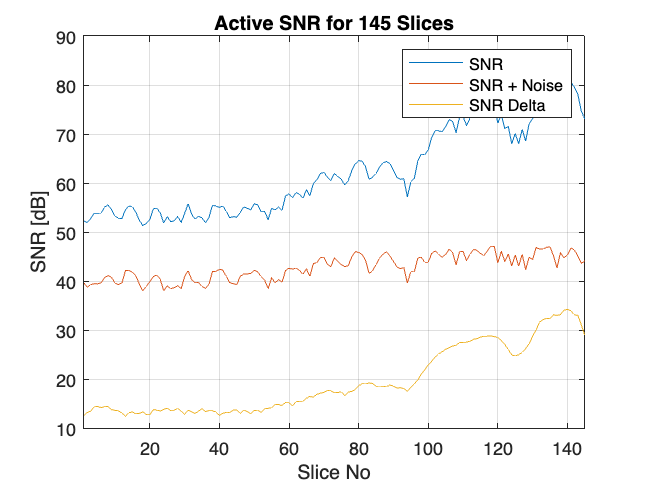

% exp_graph = repo_directory + '\bladeRAD-Rikki\figures\experiment_' + experiment_number + '_active' + '\snr_vs_slice'; % user defined export directory
fig_name = figure_directory + bracket + figure_title;
% exp_graph + '\' + figure_title;
%savefig(inputstructure.name + ' SNR for ' + length(inputdata) + ' Slices ')
%saveas(fig, fig_name, 'png')
savefig(figure_title)
saveas(fig, fig_name, 'png')

## Create video of Passive range-Doppler slices

fig =   Figure (4) with properties:

      Number: 4
        Name: ''
       Color: [1 1 1]
    Position: [616 498 560 420]
       Units: 'pixels'

  Show all properties


i = 1

i = 2

i = 3

i = 4

i = 5

i = 6

i = 7

i = 8

i = 9

i = 10

i = 11

i = 12

i = 13

i = 14

i = 15

i = 16

i = 17

i = 18

i = 19

i = 20

i = 21

i = 22

i = 23

i = 24

i = 25

i = 26

i = 27

i = 28

i = 29

i = 30

i = 31

i = 32

i = 33

i = 34

i = 35

i = 36

i = 37

i = 38

i = 39

i = 40

i = 41

i = 42

i = 43

i = 44

i = 45

i = 46

i = 47

i = 48

i = 49

i = 50

i = 51

i = 52

i = 53

i = 54

i = 55

i = 56

i = 57

i = 58

i = 59

i = 60

i = 61

i = 62

i = 63

i = 64

i = 65

i = 66

i = 67

i = 68

i = 69

i = 70

i = 71

i = 72

i = 73

i = 74

i = 75

i = 76

i = 77

i = 78

i = 79

i = 80

i = 81

i = 82

i = 83

i = 84

i = 85

i = 86

i = 87

i = 88

i = 89

i = 90

i = 91

i = 92

i = 93

i = 94

i = 95

i = 96

i = 97

i = 98

i = 99

i = 100

i = 101

i = 102

i = 103

i = 104

i = 105

i = 106

i = 107

i = 108

i = 109

i = 110

i = 111

i = 112

i = 113

i = 114

i = 115

i = 116

i = 117

i = 118

i = 119

i = 120

i = 121

i = 122

i = 123

i = 124

i = 125

i = 126

i = 127

i = 128

i = 129

i = 130

i = 131

i = 132

i = 133

i = 134

i = 135

i = 136

i = 137

i = 138

i = 139

i = 140

i = 141

i = 142

i = 143

i = 144

i = 145

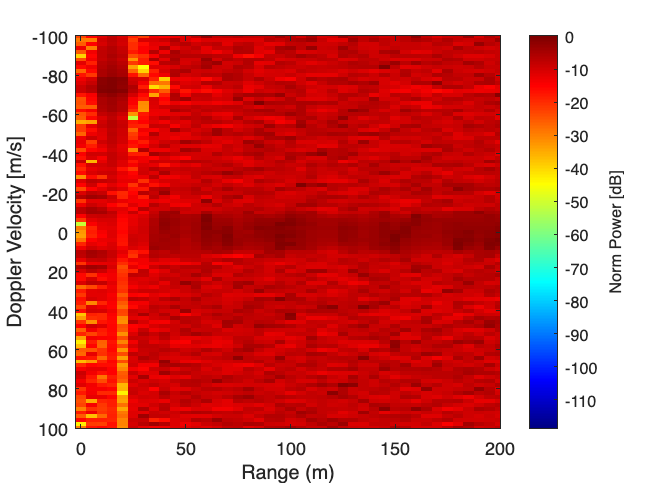

if inputstructure.name == "Active"
    if pc ==1
        video_name = video_directory...
            + bracket + "SNR Active Data"...
            + ".avi";
    elseif pc ==2
        display('pc 3 type path undefined by User')
    elseif pc ==3
        display('pc 3 type path undefined by User')
    else
        display('Undefined by User')
    end    
    video_title = "SNR Active Data";
    dynamic_range = +inf;
    max_range = 200;
    max_doppler = 100;
    frame_rate = 1/(capture_duration/active.number_cpi);
    createVideo(slices_range_doppler,frame_rate,...
        active.range_axis,max_range,...
        active.doppler_axis,max_doppler,...
        dynamic_range,video_name,video_title);
end

## Plot Signal Peak and Matrix Index Across All Slices

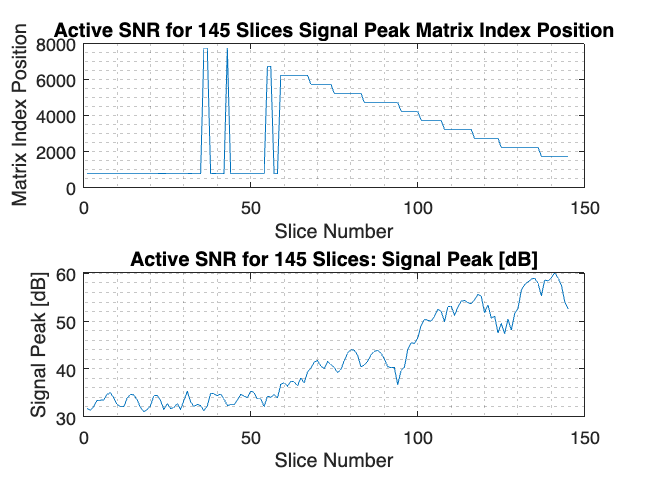

figure
subplot(2, 1, 1);
plot(1:length(signal_idx), signal_idx)
hold on
title(figure_title + ' Signal Peak Matrix Index Position');
ylabel('Matrix Index Position');
xlabel('Slice Number');  

% ylim([- 120 120]) % ([-max_doppler max_doppler]); % Doppler Limit
% xlim([-inf max_range]);   % Range Limit
grid minor 

subplot(2, 1, 2);
plot(1:length(signal), signal)
title(figure_title + ': Signal Peak [dB]');
ylabel('Signal Peak [dB]');
xlabel('Slice Number') ;  
grid minor 
hold off

Save figure to repo

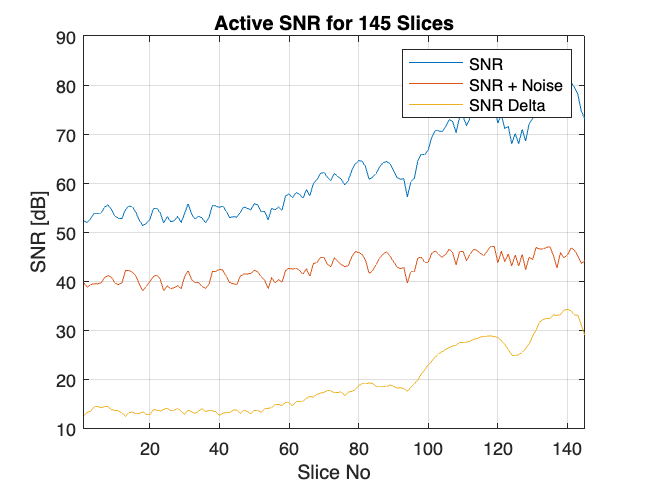

fig_name = figure_directory + bracket + figure_title + ' Signal Peak';
savefig(figure_title)
saveas(fig, fig_name, 'png')